# T3-01. Getting an AR model from a target autocovariance function

## Introduction

In this tutorial you will learn how to obtain an AR model that reproduces to some extent a predefined autocovariance function. The accuracy of the obtained model can be checked by comparing the target autocovariance function and the theoretical autocovariance function of the obtained AR model. 

Note that AR models are time series model, thus, they are usually estimated from data. However, the procedure involves first an estimation of the autocovariance function of the data, and then the AR model obtention from the autocovariance function.

The ability of the AR model to reproduce a target autocovariance function depends on the model order, the model structure (lags considered) and the selected autocovariance equations to obtain the model coefficients. A detailed description can be found at **[1]**. In this tutorial, we will assume AR(3).

The dataset employed in this tutorial is 'datasets/dataset_01_AR', which includes a restricted AR model employed in Section 3.1 of **[1]**.

**[1]** Gallego-Castillo, C. et al., A tutorial on reproducing a predefined autocovariance function through AR models: Application to stationary homogeneous isotropic turbulence, Stochastic Environmental Research and Risk Assessment. DOI: 10.1007/s00477-021-02156-0.

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

Nf = 100;  % number of elements of the frequency vector


%%% Plot parameters
CC = colororder;
color_target = [0 0 0];
color_case0 = 0.7*[1 1 1];
color_case1 = CC(1,:);
color_case2 = CC(2,:);
color_case3 = CC(3,:);
color_case4 = CC(4,:);
linewidth = 3;
font_size = 18;
figure_position = [0 0 1000 600];
figure_position_2 = [0 0 1000 1000];
M_max_plot = 30;

Load the dataset. It consists of the theoretical autocovariance function and the theoretical spectrum of an AR model. Refer to them as '*target*'. Retrieve the number of lags from the target autocovariance function, and use it to initialise a `gamma` object.

load dataset_01_AR gamma_AR S_AR

gamma_target = gamma_AR;
S_target = S_AR;
clear gamma_AR S_AR;

M = gamma_target.x_parameters.M;

gamma0 = initialise_gamma('M',M);

Initialise a `mVARboptions` object with defaul values. This object provides control on different options, such as the method to solve the variance equations to get the model coefficients, see function `initialise_mVARboptions` for details.

mVARboptions = initialise_mVARboptions();

### Case 0: Yule-Walker equations

This case corresponds to the most common methodology to obtain an AR model: the assumption of unrestricted scheme (consecutive lags in the model structure), here given by `j_vector`, and the use of autocovariance equations corresponding to lags `l_vector = j_vector`.

j_vector = [1 2 3];
l_vector = [1 2 3];

AR_case0 = initialise_AR('j_vector',j_vector);

AR_case0 = get_AR_gamma(gamma_target, AR_case0, l_vector, mVARboptions);

gamma_case0 = get_gamma_AR(AR_case0,gamma0);

fprintf('j_vector is [%d, %d, %d] \n', AR_case0.restricted_parameters.j_vector)

j_vector is [1, 2, 3] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case0.restricted_parameters.a_vector)

a_vector is [1.22, -0.57, 0.10] 


fprintf('b is %.2f \n',AR_case0.restricted_parameters.b)

b is 0.51 


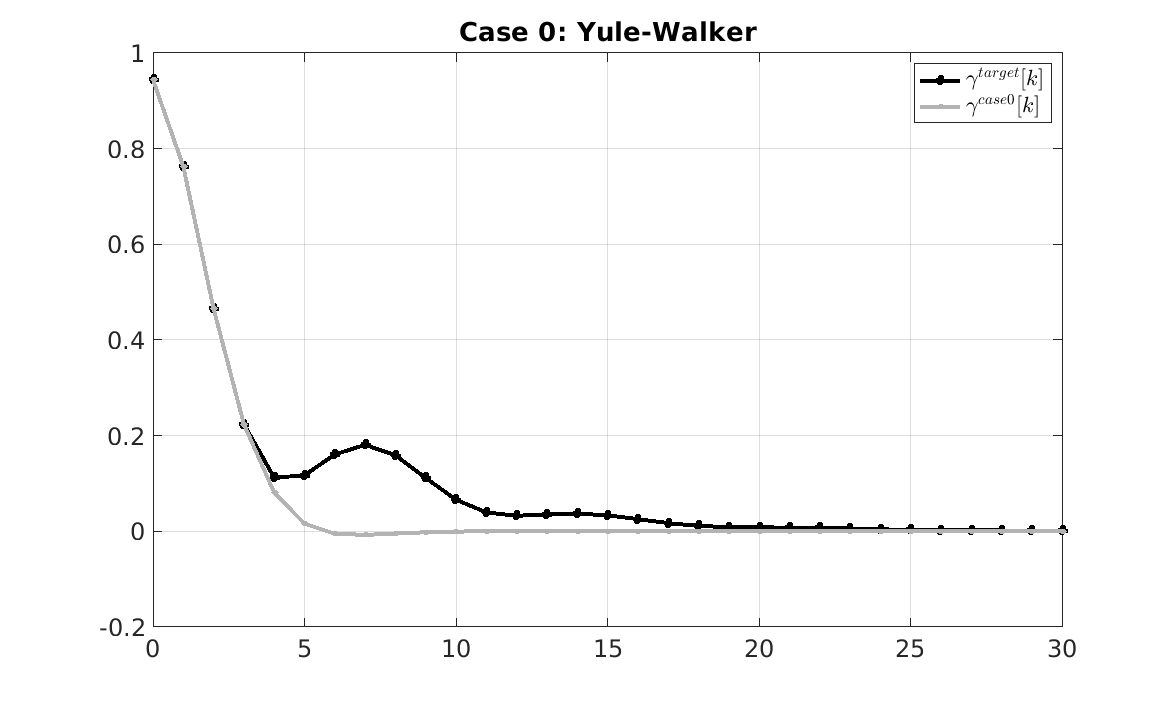



% Plot

figure

x = gamma_target.xlag_values;
y = gamma_target.y_values;
plot(x,y,'O-','color',color_target,'MarkerFaceColor',color_target,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case0.xlag_values;
y = gamma_case0.y_values;
plot(x,y,'O-','color',color_case0,'MarkerFaceColor',color_case0,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 0: Yule-Walker')
legend({'$\gamma^{target}[k]$','$\gamma^{case0}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 1: unrestricted AR(3) with determined system of equations

In this case, the assumption `j_vector = l_vector` is relaxed. The AR model is unrestricted becase the considered lags are consecutive (1, 2 and 3), but the autocovariance equations selected for obtaining the model coefficients are those corresponding to lags 1, 2 and 4. Because the number of covariance equations are the same as the number of unknowns, the system of equations is determined.

j_vector = [1 2 3];
l_vector = [1 2 4];

AR_case1 = initialise_AR('j_vector',j_vector);

AR_case1 = get_AR_gamma(gamma_target, AR_case1, l_vector, mVARboptions);

gamma_case1 = get_gamma_AR(AR_case1,gamma0);

fprintf('j_vector is [%d, %d, %d] \n', AR_case1.restricted_parameters.j_vector)

j_vector is [1, 2, 3] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case1.restricted_parameters.a_vector)

a_vector is [1.27, -0.69, 0.20] 


fprintf('b is %.2f \n',AR_case1.restricted_parameters.b)

b is 0.50 


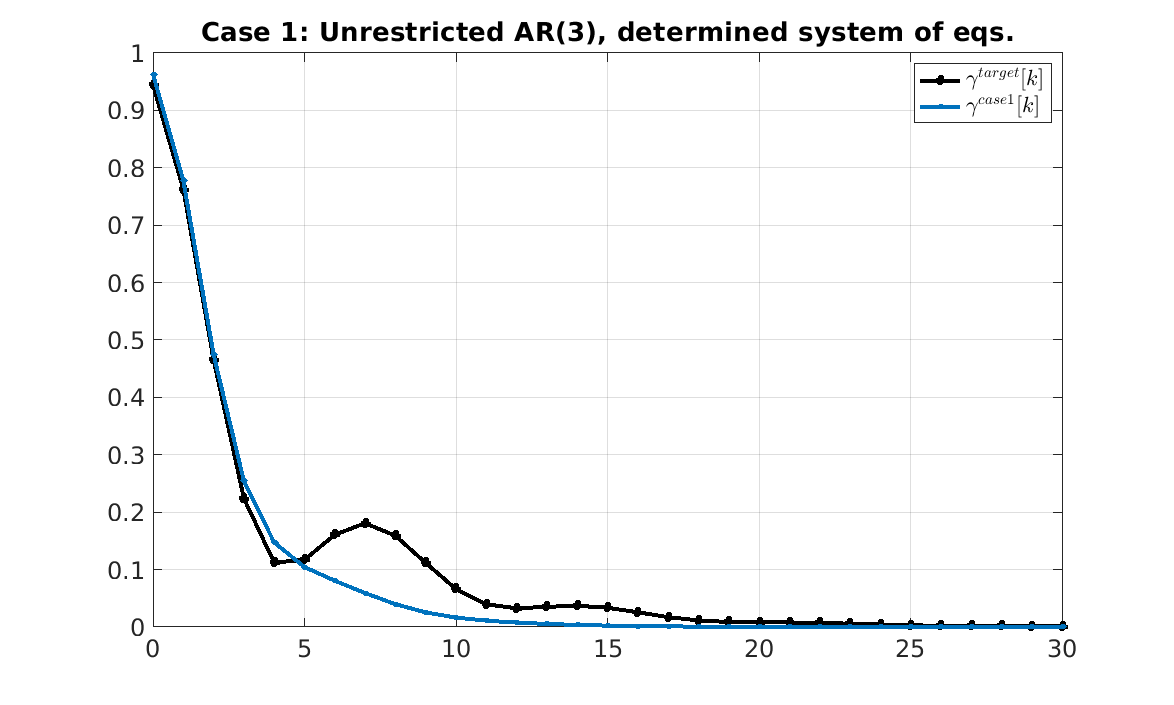



% Plot

figure

x = gamma_target.xlag_values;
y = gamma_target.y_values;
plot(x,y,'O-','color',color_target,'MarkerFaceColor',color_target,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case1.xlag_values;
y = gamma_case1.y_values;
plot(x,y,'O-','color',color_case1,'MarkerFaceColor',color_case1,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 1: Unrestricted AR(3), determined system of eqs.')
legend({'$\gamma^{target}[k]$','$\gamma^{case1}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 2: unrestricted AR(3) with overdetermined system of equations

In this case, the number of covariance equations employed to obtain the model coefficients is larger than the number of unknowns. The system of equations is overdetermined, and the solution is obtained through MSE. This strategy allows including information of the target autocovariance function for high lags, improving the general fitting.

j_vector = [1 2 3];
l_vector = 1:20;

AR_case2 = initialise_AR('j_vector',j_vector);

AR_case2 = get_AR_gamma(gamma_target, AR_case2, l_vector, mVARboptions);

gamma_case2 = get_gamma_AR(AR_case2,gamma0);

fprintf('j_vector is [%d, %d, %d] \n', AR_case2.restricted_parameters.j_vector)

j_vector is [1, 2, 3] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case2.restricted_parameters.a_vector)

a_vector is [1.47, -1.00, 0.34] 


fprintf('b is %.2f \n',AR_case2.restricted_parameters.b)

b is 0.46 


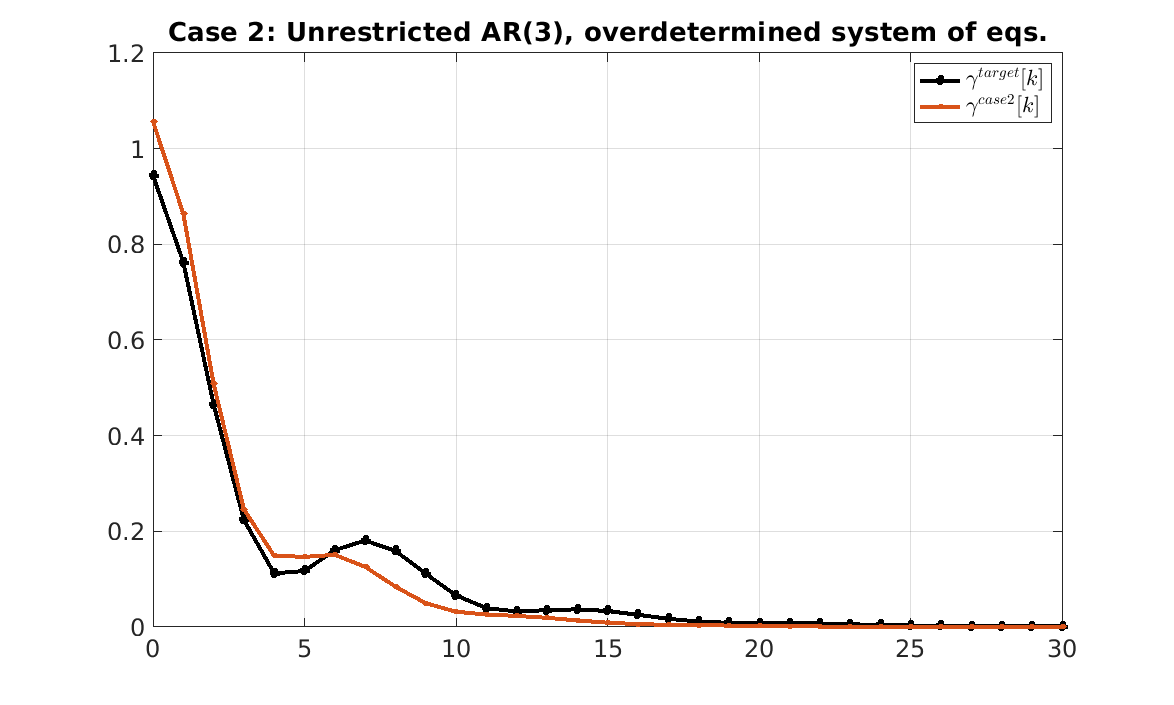



% Plot

figure

x = gamma_target.xlag_values;
y = gamma_target.y_values;
plot(x,y,'O-','color',color_target,'MarkerFaceColor',color_target,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case2.xlag_values;
y = gamma_case2.y_values;
plot(x,y,'O-','color',color_case2,'MarkerFaceColor',color_case2,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 2: Unrestricted AR(3), overdetermined system of eqs.')
legend({'$\gamma^{target}[k]$','$\gamma^{case2}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 3: Restricted AR(3) with determined system of equations

In this case a restricted AR model is considered. The AR structure is given by lags 1, 2 and 4.

j_vector = [1 2 4];
l_vector = [1 2 4];

AR_case3 = initialise_AR('j_vector',j_vector);

AR_case3 = get_AR_gamma(gamma_target, AR_case3, l_vector, mVARboptions);

gamma_case3 = get_gamma_AR(AR_case3,gamma0);

fprintf('j_vector is [%d, %d, %d] \n', AR_case3.restricted_parameters.j_vector)

j_vector is [1, 2, 4] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case3.restricted_parameters.a_vector)

a_vector is [1.22, -0.54, 0.10] 


fprintf('b is %.2f \n',AR_case3.restricted_parameters.b)

b is 0.50 


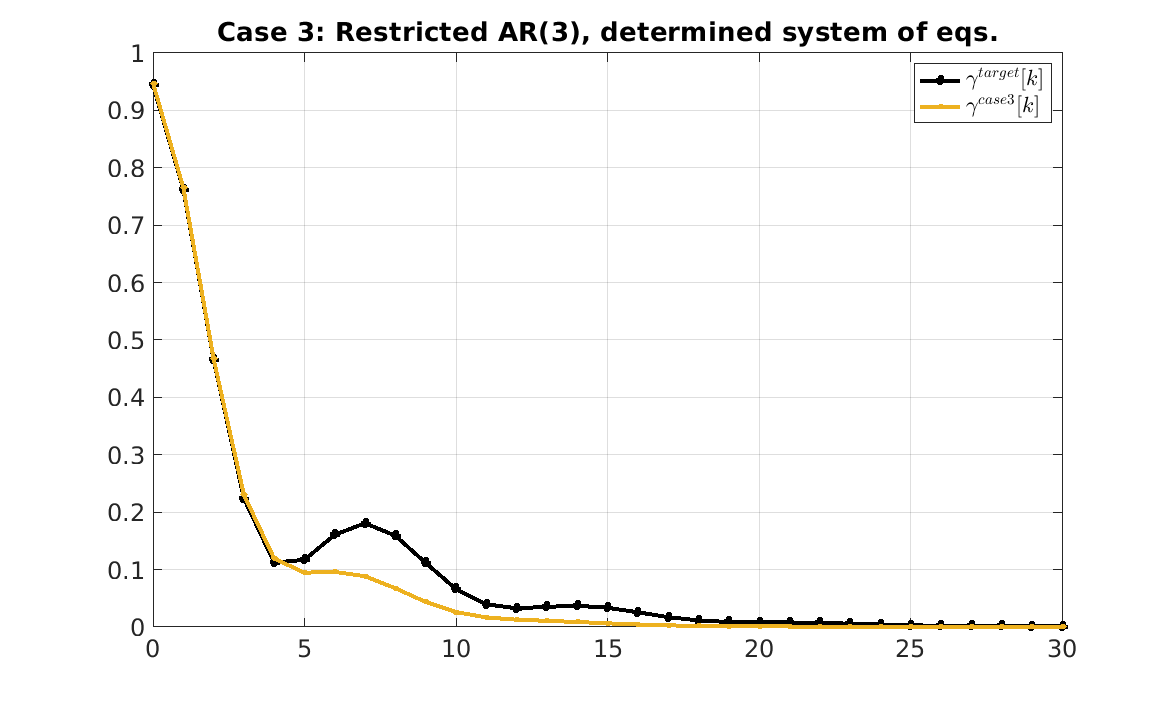



% Plot

figure

x = gamma_target.xlag_values;
y = gamma_target.y_values;
plot(x,y,'O-','color',color_target,'MarkerFaceColor',color_target,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case3.xlag_values;
y = gamma_case3.y_values;
plot(x,y,'O-','color',color_case3,'MarkerFaceColor',color_case3,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 3: Restricted AR(3), determined system of eqs.')
legend({'$\gamma^{target}[k]$','$\gamma^{case3}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Case 4: Restricted AR(3) with overdetermined system of equations

j_vector = [1 2 4];
l_vector = 1:20;

AR_case4 = initialise_AR('j_vector',j_vector);

AR_case4 = get_AR_gamma(gamma_target, AR_case4, l_vector, mVARboptions);

gamma_case4 = get_gamma_AR(AR_case4,gamma0);

fprintf('j_vector is [%d, %d, %d] \n', AR_case4.restricted_parameters.j_vector)

j_vector is [1, 2, 4] 


fprintf('a_vector is [%.2f, %.2f, %.2f] \n', AR_case4.restricted_parameters.a_vector)

a_vector is [1.32, -0.66, 0.15] 


fprintf('b is %.2f \n',AR_case4.restricted_parameters.b)

b is 0.48 


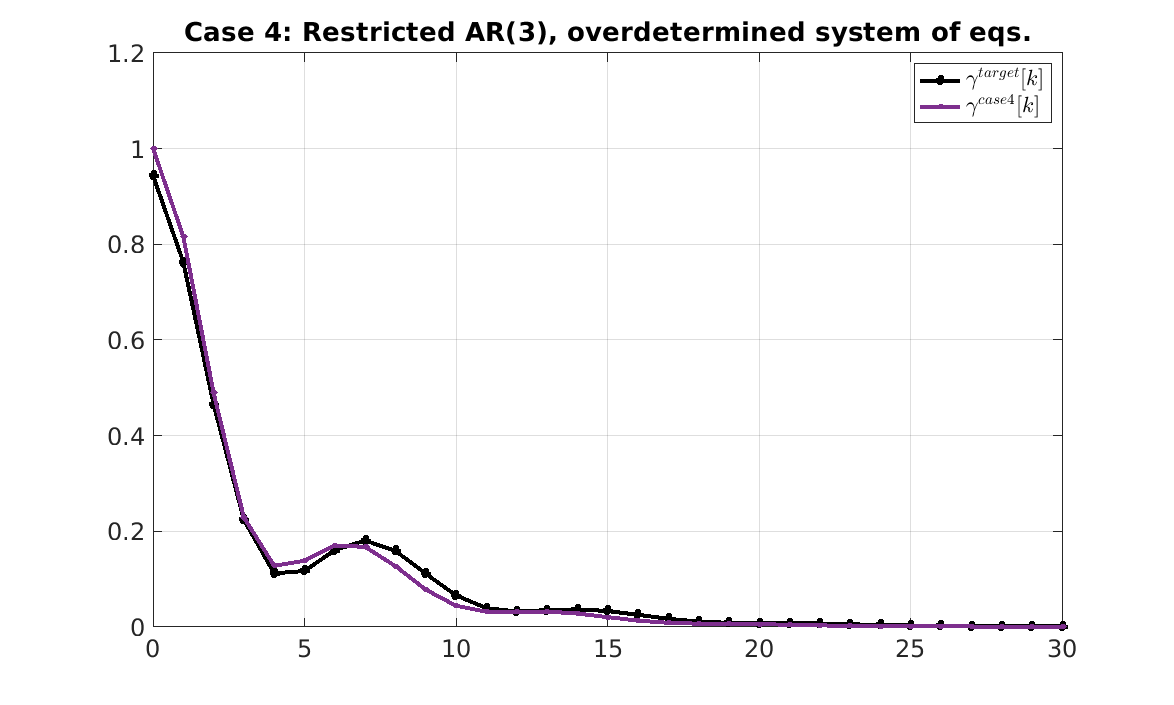



% Plot

figure

x = gamma_target.xlag_values;
y = gamma_target.y_values;
plot(x,y,'O-','color',color_target,'MarkerFaceColor',color_target,...
                                   'LineWidth',linewidth,...
                                   'markersize',5)
hold on
x = gamma_case4.xlag_values;
y = gamma_case4.y_values;
plot(x,y,'O-','color',color_case4,'MarkerFaceColor',color_case4,...
                                      'LineWidth',linewidth,...
                                      'markersize',3)

title('Case 4: Restricted AR(3), overdetermined system of eqs.')
legend({'$\gamma^{target}[k]$','$\gamma^{case4}[k]$'},'interpreter','latex')
grid on
xlim([0 M_max_plot])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

### Comparison of PSDs

Get the theoretical spectra of the obtained AR models, and compare them with the target spectrum.

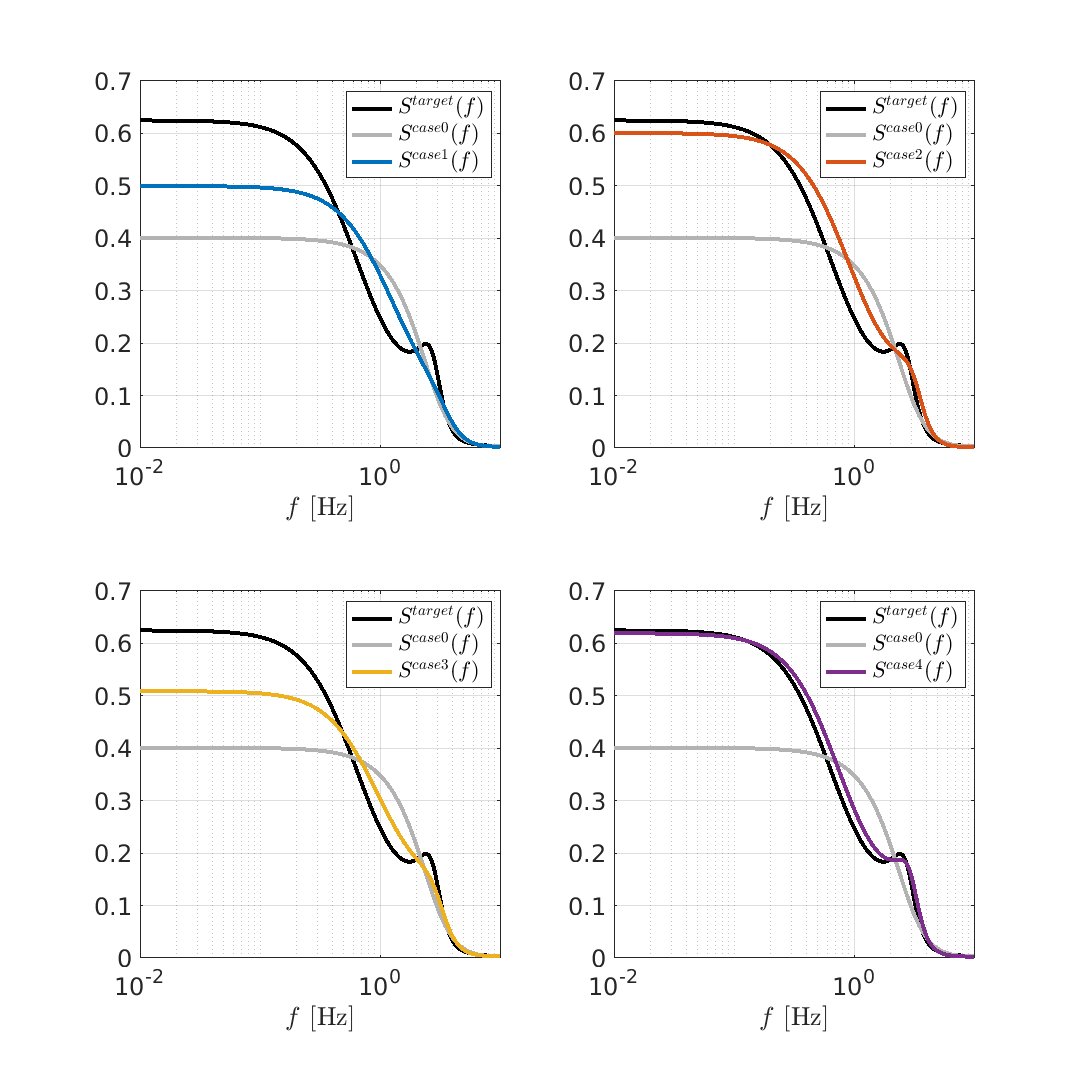

S0 = initialise_S('ind_var',S_target.ind_var,...
                  'x_values',S_target.x_values,...
                  'x_max',S_target.x_parameters.x_max);

S_case0 = get_S_AR(AR_case0, S0);
S_case1 = get_S_AR(AR_case1, S0);
S_case2 = get_S_AR(AR_case2, S0);
S_case3 = get_S_AR(AR_case3, S0);
S_case4 = get_S_AR(AR_case4, S0);


figure

subplot(2,2,1)

x = S_target.x_values;
y = S_target.y_values;
plot(x,y,'-','color',color_target,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case1.y_values;
plot(x,y,'-','color',color_case1,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{target}(f)$','$S^{case0}(f)$','$S^{case1}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


subplot(2,2,2)

x = S_target.x_values;
y = S_target.y_values;
plot(x,y,'-','color',color_target,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case2.y_values;
plot(x,y,'-','color',color_case2,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{target}(f)$','$S^{case0}(f)$','$S^{case2}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


subplot(2,2,3)

x = S_target.x_values;
y = S_target.y_values;
plot(x,y,'-','color',color_target,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case3.y_values;
plot(x,y,'-','color',color_case3,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{target}(f)$','$S^{case0}(f)$','$S^{case3}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


subplot(2,2,4)

x = S_target.x_values;
y = S_target.y_values;
plot(x,y,'-','color',color_target,'LineWidth',linewidth)
hold on
y = S_case0.y_values;
plot(x,y,'-','color',color_case0,'LineWidth',linewidth)
y = S_case4.y_values;
plot(x,y,'-','color',color_case4,'LineWidth',linewidth)
xlabel('$f$ [Hz]', 'Interpreter','latex')
grid on
legend({'$S^{target}(f)$','$S^{case0}(f)$','$S^{case4}(f)$'},...
        'Interpreter','latex')
set(gca,'fontsize',font_size)
set(gca,'xscale','log')


set(gcf,'position',figure_position_2)

## Remarks

- As it has been demonstrated, even when the model order is fixed, $p=3$, different decission on the model structure (restricted or unrestricted) and selected covariance equations for obtaining the model (including determined or overdetermined systems) lead to different AR models. These models show different performances in reproducing the target autocovariance function and, consequently, the target spectrum.

- The previous comment suggests that there is room for optimising both the AR model structure and the selected covariance equations. For a detailed discussion, see the above mentioned reference **[1]**.